dataFile = fullfile(toolboxdir('vision'), 'visiondata', 'livingRoom.mat');
load(dataFile);

% Extract two consecutive point clouds and use the first point cloud as
% reference.
ptCloudRef = livingRoomData{1};
ptCloudCurrent = livingRoomData{2};

gridSize = 0.1;
fixed = pcdownsample(ptCloudRef, 'gridAverage', gridSize);
moving = pcdownsample(ptCloudCurrent, 'gridAverage', gridSize);

% Note that the downsampling step does not only speed up the registration,
% but can also improve the accuracy.

tform = pcregistericp(moving, fixed, 'Metric','pointToPlane','Extrapolate', true);
ptCloudAligned = pctransform(ptCloudCurrent,tform);

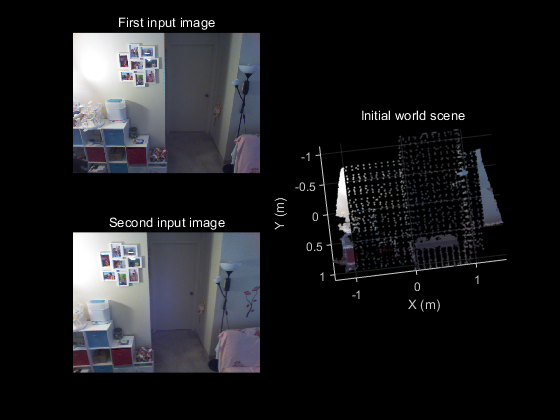

mergeSize = 0.1;
ptCloudScene = pcmerge(ptCloudRef, ptCloudAligned, mergeSize);

% Visualize the input images.
figure
subplot(2,2,1)
imshow(ptCloudRef.Color)
title('First input image','Color','w')
drawnow

subplot(2,2,3)
imshow(ptCloudCurrent.Color)
title('Second input image','Color','w')
drawnow

% Visualize the world scene.
subplot(2,2,[2,4])
pcshow(ptCloudScene, 'VerticalAxis','Y', 'VerticalAxisDir', 'Down')
title('Initial world scene')
xlabel('X (m)')
ylabel('Y (m)')
zlabel('Z (m)')